## The problem 

the base frame of the work peice needs to be translated and rotated about the z axis to reflect the physical configuration of the workpeice with respect to the base frame of the robot arm as they are physically placed in the real world. 

### Assumptions

- The orientation of the workpeice will only differ from the orientation of the robot base by a rotation about the z axis, the yaw angle

- The position of the workpeice will be a constant offset away          

- p = (x_displacement, y_displacement, z_displacement)

- We have the configuration frames of the offsets with respect to the base frame of the workpeice

- For the sake of this demo, p = (0, 5000, 0), and the yaw angle to rotate by is 50 degrees

### Plan

- First we assume the base frame of the workpeice and base frame of the robot are the same

- We than rotate the workpeice frame ( and all offset frames), by the correct yaw angle that will eventually match the actual physical configuration

- Finally we translate these frames to match the physical distance between the base from of the robot and the base frame of the work peice

- Assuming that the end effector position can be set by specifying a position with respect to the base frame of the robot, we can now reach the offsets on the workpeice

%%  Import the object to read
% [V F N name] = stlReadAscii("egg_x_50.stl");
[V F N name] = stlReadBinary("egg_x_50.stl");

#### 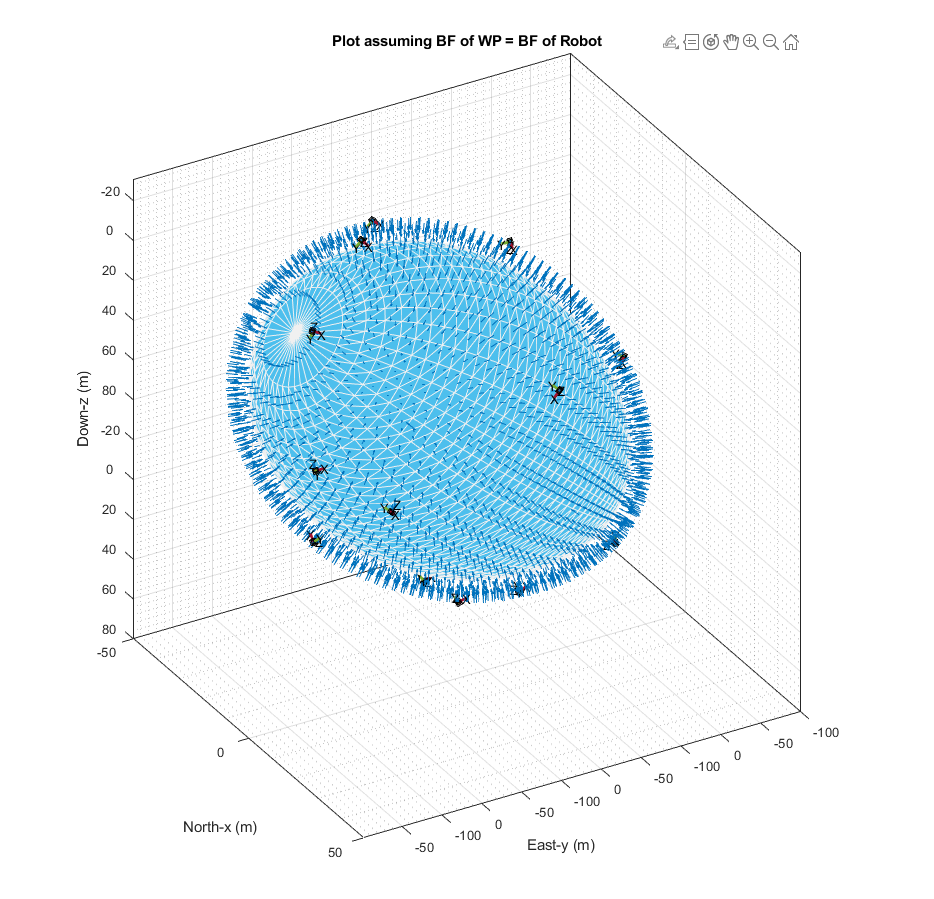

#### Setting the Transformation Parameters

%% Set transformation parameters
x_displacement = 0; 
y_displacement = 5000;
z_displacement = 0;
yaw_angle_rotate = 50;
% p = [x_displacement; y_displacement; z_displacement];
% T = [eye(3) p; 0 0 0 1]

####  Get triangle centroids and compute offsets

[t,c] = getTriangles(F,V); % get triangles and centroids to calculate poses
offsets = c + 5*N;
invertedNormals = -1*N;

#### Get Poses

poses = getPose(offsets,invertedNormals);
xyz= poses(:,4:6);
q = quaternion([xyz(:,1) xyz(:,2) xyz(:,3)],"eulerd","XYZ","frame");

#### 1) Compute rotation matrix and a) rotate frames

rotms =quat2rotm(q);
rot_z = rotz(yaw_angle_rotate);
rotated_frames = pagemtimes(rot_z,rotms);
rotated_frames_q =  rotm2quat(rotated_frames);
rotated_frames_q = quaternion(rotated_frames_q);

#### b) rotate frame positions 

rotated_offsets=pagemtimes(rot_z,offsets')';

#### c) rotate vertices and direction vectors for plotting patches and quivers ( only for visual verification) 

rot_v=pagemtimes(rot_z,V')';
rot_inverted_normal = pagemtimes(rot_z,invertedNormals')';

#### 2) Translate frames

translated_rotated_offsets = [];
translated_rotated_offsets(:,1) = rotated_offsets(:,1)+x_displacement; 
translated_rotated_offsets(:,2) = rotated_offsets(:,2)+y_displacement; 
translated_rotated_offsets(:,3) = rotated_offsets(:,3)+z_displacement; 

#### b) translate vertices for plotting patches ( only for visual verification) 

translated_rotated_V = [];
translated_rotated_V(:,1) = rot_v(:,1)+x_displacement; 
translated_rotated_V(:,2) = rot_v(:,2)+y_displacement; 
translated_rotated_V(:,3) = rot_v(:,3)+z_displacement; 

#### Plotting

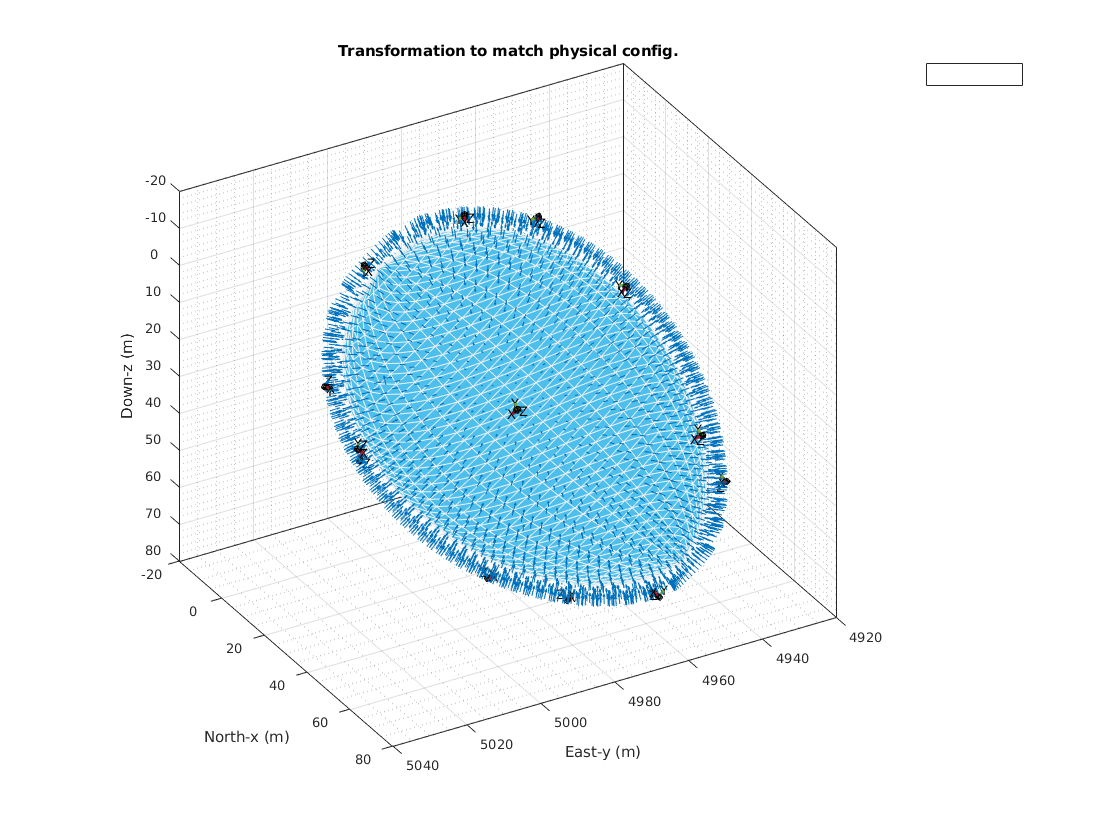

tp = theaterPlot();
op = orientationPlotter(tp);
hold on
xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");
h = patch("Faces",F,"Vertices",translated_rotated_V);
set(h,"FaceColor",[0.30,0.75,0.93],"EdgeColor",[0.94,0.94,0.94])
quiver3(translated_rotated_offsets(:,1),translated_rotated_offsets(:,2),translated_rotated_offsets(:,3),rot_inverted_normal(:,1),rot_inverted_normal(:,2),rot_inverted_normal(:,3))
for i=1:200:size(rot_inverted_normal,1)
    
    poseplot(rotated_frames_q(i),translated_rotated_offsets(i,:))

end
% title("Plot assuming BF of WP = BF of Robot")
title("Transformation to match physical config.")